im_confocal_m=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C2-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_m,[]);

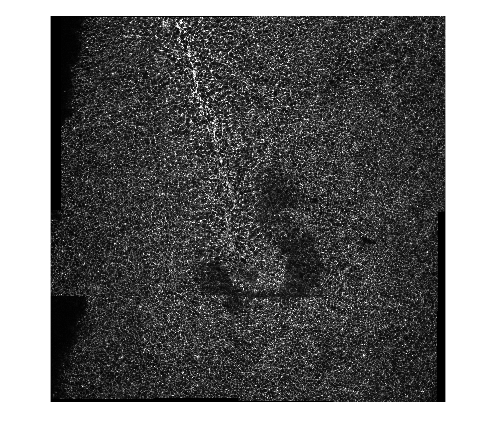

im_confocal_a=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C3-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_a,[]);

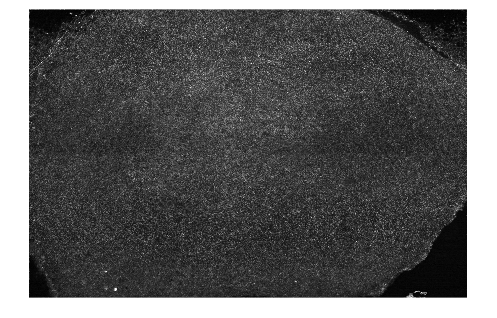

im_245=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\DSLM_expk\expk0245\0003_merge\merged_images\merge\img_0006.tif'));
imshow(im_245,[]);

DLSM_pixel=.65 ;%microns
confocal_pixel = 1/5.548 ;
confocal_tile = @(x) round(x*DLSM_pixel/confocal_pixel); %to get 
%equivalent tile size to 180, 256, etc pixel tiles on DLSM images

tile_size_DSLM=180;
tile_size_confocal=confocal_tile(tile_size_DSLM)

tile_size_confocal = 649

FT = @(x) abs(fftshift(fft2(perdecomp(x))));

loc1_DSLM = [6200, 2000] %cells right of streak

loc1_DSLM =         6200        2000


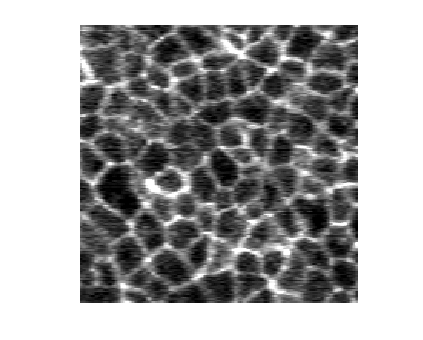

data=im_245(loc1_DSLM(2):loc1_DSLM(2)+tile_size_DSLM, loc1_DSLM(1):loc1_DSLM(1)+tile_size_DSLM);
imshow(imadjust(data),[]);

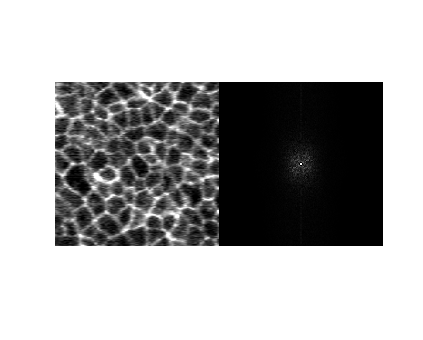

FT_loc1_DSLM =FT(data);
montage({imadjust(data)./1,(FT_loc1_DSLM)./100000});

loc2_DSLM = [6800, 4300] %black lower right corner

loc2_DSLM =         6800        4300


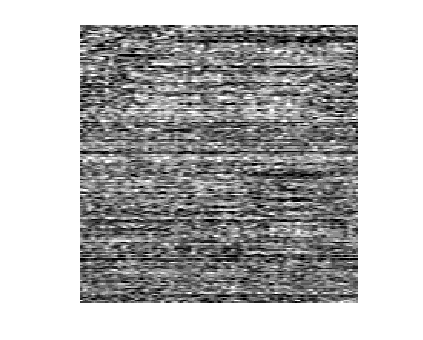

data2black=im_245(loc2_DSLM(2):loc2_DSLM(2)+tile_size_DSLM, loc2_DSLM(1):loc2_DSLM(1)+tile_size_DSLM);
imshow(imadjust(data2black),[]);

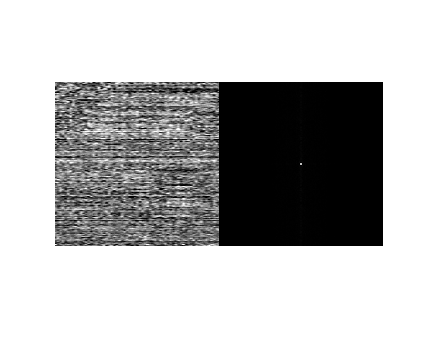

FT_loc2_DSLM =FT(data2black);
montage({imadjust(data2black)./1,(FT_loc2_DSLM)./100000});

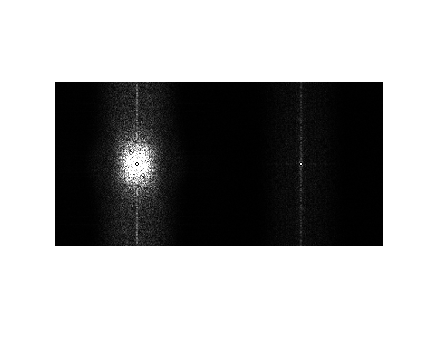

montage({(FT_loc1_DSLM)./10000,(FT_loc2_DSLM)./10000});

stripewidth = 4

stripewidth = 4

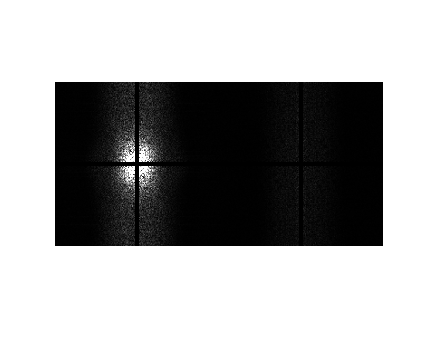

montage({stripemask(FT_loc1_DSLM)./10000,stripemask(FT_loc2_DSLM)./10000});

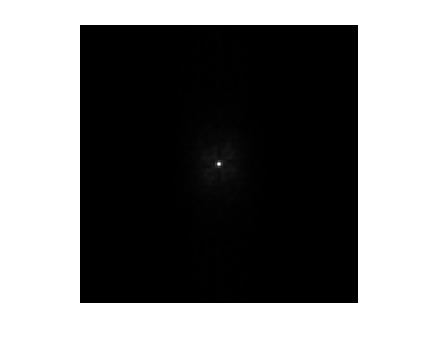

imshow((imgaussfilt(FT_loc1_DSLM,1)-imgaussfilt(FT_loc2_DSLM,1))./100,[]);

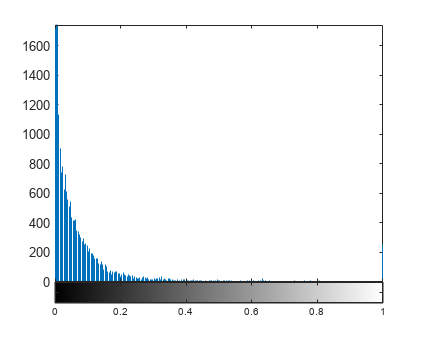

imhist(FT_loc1_DSLM/(.01*max(FT_loc1_DSLM, [], "all")));

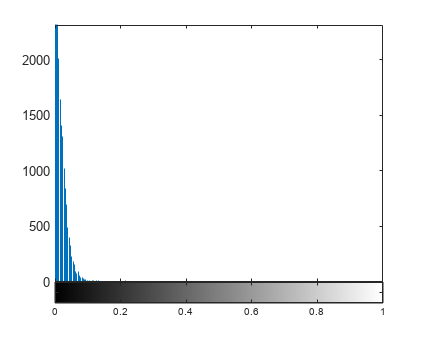

imhist(FT_loc2_DSLM/(.01*max(FT_loc1_DSLM, [], "all")));

stripewidth = 4

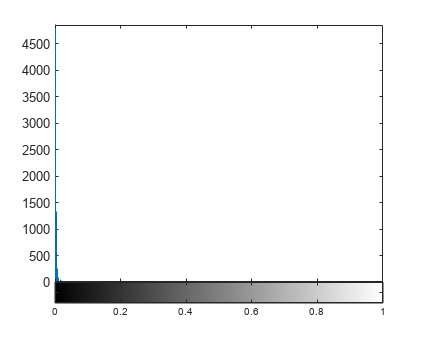

imhist(stripemask(FT_loc1_DSLM)./(max(FT_loc1_DSLM, [], "all")));

xlim([0, .1])
ylim([0,1500])

imhist(stripemask(FT_loc2_DSLM)./(max(FT_loc1_DSLM, [], "all")));

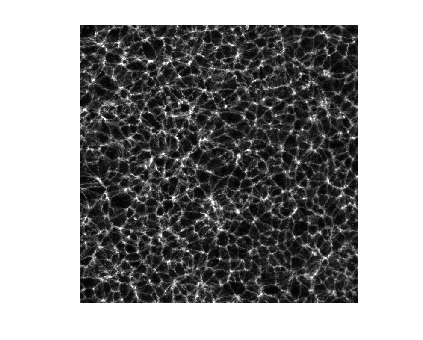

loc1 = [2700,850]; %in upper right uniform area
tile1a = im_confocal_a(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1a,[])

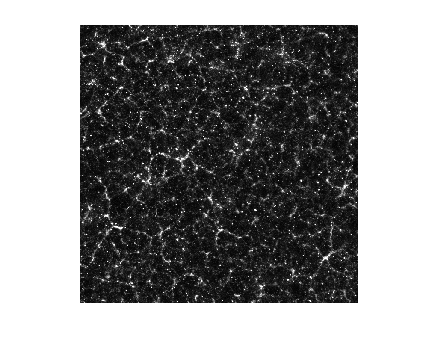

tile1m = im_confocal_m(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1m,[])

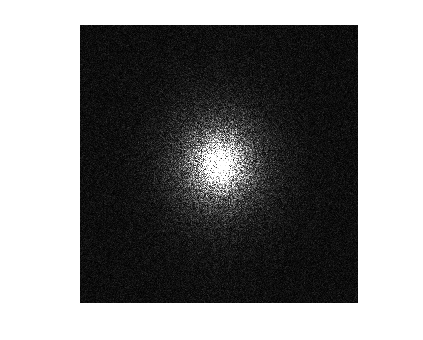

imshow(FT(tile1a),[0,100000])

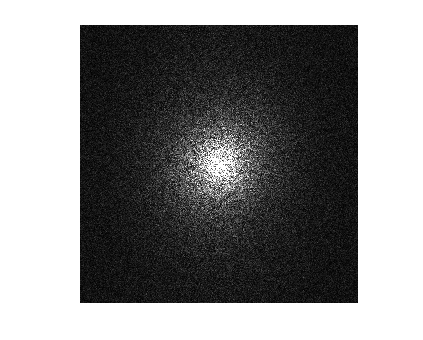

imshow(FT(tile1m),[0,100000])

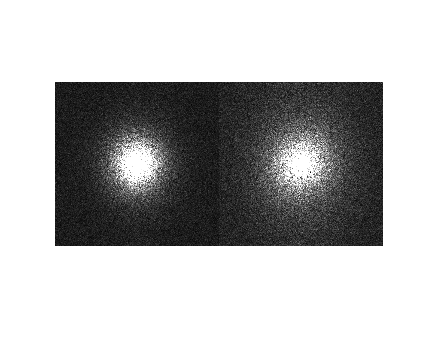

montage({FT(tile1a), FT(tile1m)},[], DisplayRange=[0,50000])

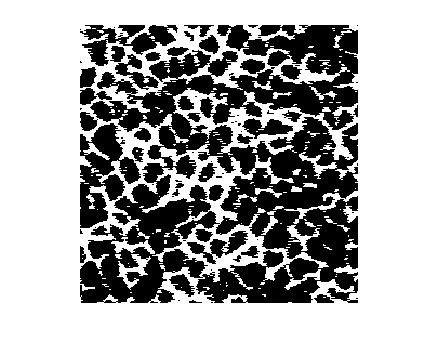

imshow(imbinarize(data),[])

function im=stripemask(im)
stripewidth=4
                dims=size(im);
                Mask = zeros(dims(1), dims(2), "logical");
                Mask(round((dims(1)-stripewidth)/2):round((dims(1)+stripewidth)/2),:) = true;
                Mask(:,round((dims(2)-stripewidth)/2):round((dims(2)+stripewidth)/2)) = true;
                im(logical(Mask)) = 0;
end